# Image processing final project

%main 
% Uploading an image that will be used for the functions 
Image = imread("/Users/Rori/Desktop/ImageProcessing /Test_Images/Pepper.tif");  %Change directory

NoiseImage1= Gaussian_additive_noise(Image, 0.1, "Luminosty");
disp("Additive Gaussian Noise Y Channel Image");

Additive Gaussian Noise Y Channel Image


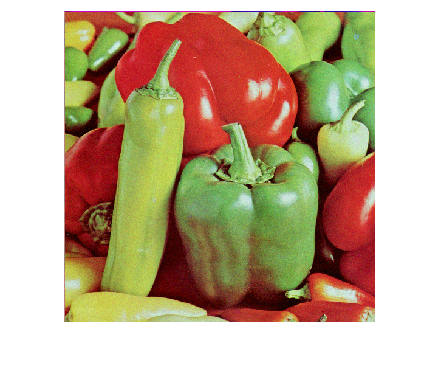

imshow(NoiseImage1); 

[mean_Y,stand_Y,mean_RGB, stand_RGB] = mean_std(NoiseImage1);
disp("mean y channel:")

mean y channel:


disp(mean_Y)

  119.3566



disp("std y channel:")

std y channel:


disp(stand_Y)

   46.2129



disp("mean RGB channel:")

mean RGB channel:


disp(mean_RGB)

  149.8165  115.7643   66.6466



disp("std RGB channel:")

std RGB channel:


disp(stand_RGB)

   45.3945   75.0777   44.3247



NoiseImage1b= Gaussian_additive_noise(Image, 0.1, "RGB");
disp("Additive Gaussian Noise RGB Channel Image");

Additive Gaussian Noise RGB Channel Image


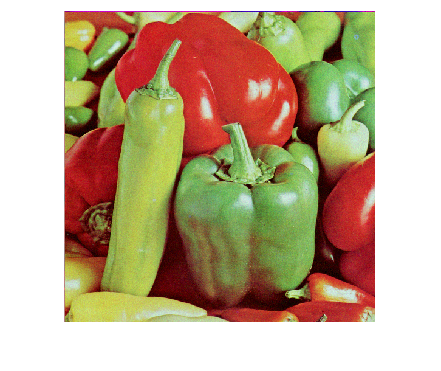

imshow(NoiseImage1b); 


NoiseImage2= impulse_noise(Image,0.05, "Luminosty");
disp("Random Impulse Noise Y Channel Image");

Random Impulse Noise Y Channel Image


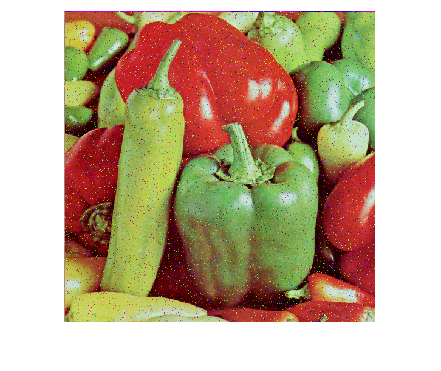

imshow(NoiseImage2); 

NoiseImage2b= impulse_noise(Image,0.05, "RGB");
disp("Random Impulse Noise RGB Channel Image");

Random Impulse Noise RGB Channel Image


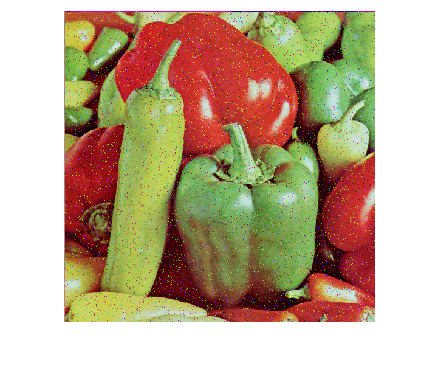

imshow(NoiseImage2b); 


FilteredImage1= rank_order_Mean_EV_filtering(NoiseImage2,"Luminosty");  
disp("Rank order EV Filter for Random Impulse Noise Y Channel Image");

Rank order EV Filter for Random Impulse Noise Y Channel Image


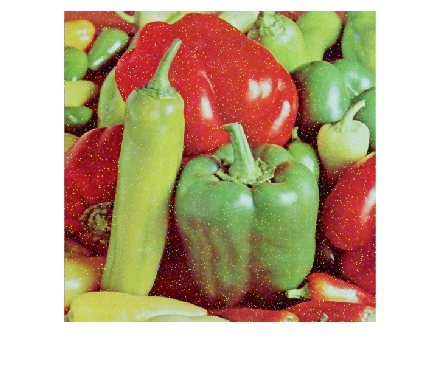

imshow(FilteredImage1); 

[RMSE_Y, PSNR_Y, RMSE_RGB, PSNR_RGB] = RMSE_PSNR(Image,FilteredImage1);
disp("RMSE Y channel")

RMSE Y channel


disp(RMSE_Y)

   12.6649



disp("PSNR Y channel")

PSNR Y channel


disp(PSNR_Y)

   26.0788



disp("RMSE RGB channel")

RMSE RGB channel


disp(RMSE_RGB)

   13.9707   21.6538   24.9510



disp("PSNR RGB channel")

PSNR RGB channel


disp(PSNR_RGB)

   25.2264   21.4201   20.1891



FilteredImage1b= rank_order_Mean_EV_filtering(NoiseImage2b,"RGB");
disp("Rank order EV Filter for Random Impulse Noise RGB Channel Image");

Rank order EV Filter for Random Impulse Noise RGB Channel Image


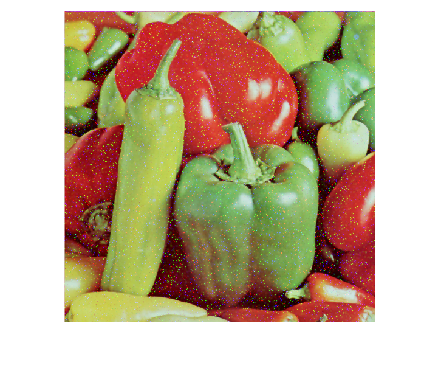

imshow(FilteredImage1b); 

[RMSE_Y, PSNR_Y, RMSE_RGB, PSNR_RGB] = RMSE_PSNR(Image,FilteredImage1b);
disp("RMSE Y channel")

RMSE Y channel


disp(RMSE_Y)

   12.6418



disp("PSNR Y channel")

PSNR Y channel


disp(PSNR_Y)

   26.0946



disp("RMSE RGB channel")

RMSE RGB channel


disp(RMSE_RGB)

   13.7177   21.6743   24.9342



disp("PSNR RGB channel")

PSNR RGB channel


disp(PSNR_RGB)

   25.3852   21.4119   20.1949



FilteredImage1c= rank_order_Mean_EV_filtering(NoiseImage1,"Luminosty");  
disp("Rank order EV Filter for Additive Gaussian Noise Y Channel Image");

Rank order EV Filter for Additive Gaussian Noise Y Channel Image


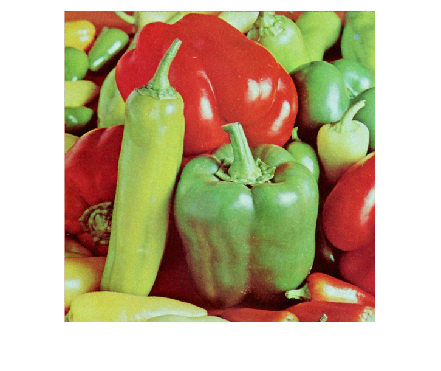

imshow(FilteredImage1c); 

[RMSE_Y, PSNR_Y, RMSE_RGB, PSNR_RGB] = RMSE_PSNR(Image,FilteredImage1c);
disp("RMSE Y channel")

RMSE Y channel


disp(RMSE_Y)

    7.9536



disp("PSNR Y channel")

PSNR Y channel


disp(PSNR_Y)

   30.1195



disp("RMSE RGB channel")

RMSE RGB channel


disp(RMSE_RGB)

    7.3008   12.6971    8.7540



disp("PSNR RGB channel")

PSNR RGB channel


disp(PSNR_RGB)

   30.8634   26.0567   29.2867



FilteredImage1d = rank_order_Mean_EV_filtering(NoiseImage1b,"RGB");
disp("Rank order EV Filter for Additive Gaussian Noise RGB Channel Image");

Rank order EV Filter for Additive Gaussian Noise RGB Channel Image


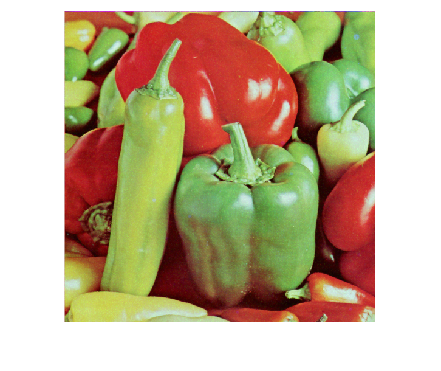

imshow(FilteredImage1d); 

[RMSE_Y, PSNR_Y, RMSE_RGB, PSNR_RGB] = RMSE_PSNR(Image,FilteredImage1d);
disp("RMSE Y channel")

RMSE Y channel


disp(RMSE_Y)

    7.9650



disp("PSNR Y channel")

PSNR Y channel


disp(PSNR_Y)

   30.1071



disp("RMSE RGB channel")

RMSE RGB channel


disp(RMSE_RGB)

    7.2956   12.7281    8.7377



disp("PSNR RGB channel")

PSNR RGB channel


disp(PSNR_RGB)

   30.8696   26.0355   29.3029




FilteredImage2= median_filtering(NoiseImage2,"Luminosty"); 
disp("Median Filter for Random Impulse Noise Y Channel Image");

Median Filter for Random Impulse Noise Y Channel Image


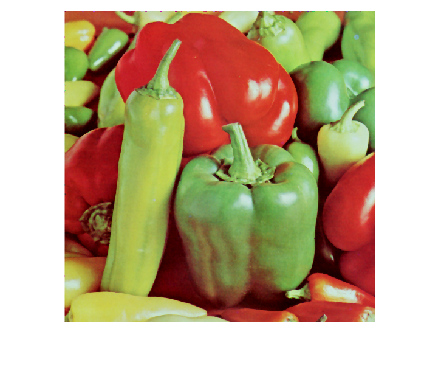

imshow(FilteredImage2); 

[RMSE_Y, PSNR_Y, RMSE_RGB, PSNR_RGB] = RMSE_PSNR(Image,FilteredImage2);
disp("RMSE Y channel")

RMSE Y channel


disp(RMSE_Y)

    6.6006



disp("PSNR Y channel")

PSNR Y channel


disp(PSNR_Y)

   31.7391



disp("RMSE RGB channel")

RMSE RGB channel


disp(RMSE_RGB)

    7.8519   10.6622    8.0507



disp("PSNR RGB channel")

PSNR RGB channel


disp(PSNR_RGB)

   30.2313   27.5739   30.0142



FilteredImage2b= median_filtering(NoiseImage2b,"RGB");
disp("Median Filter for Random Impulse Noise RGB Channel Image");

Median Filter for Random Impulse Noise RGB Channel Image


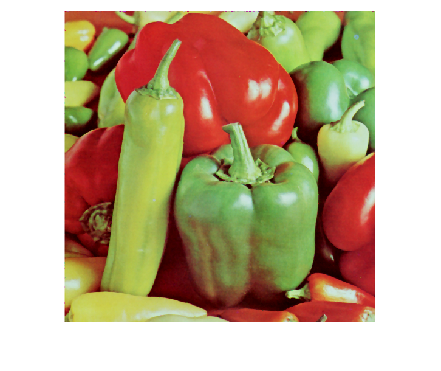

imshow(FilteredImage2b); 

[RMSE_Y, PSNR_Y, RMSE_RGB, PSNR_RGB] = RMSE_PSNR(Image,FilteredImage2b);
disp("RMSE Y channel")

RMSE Y channel


disp(RMSE_Y)

    6.5285



disp("PSNR Y channel")

PSNR Y channel


disp(PSNR_Y)

   31.8345



disp("RMSE RGB channel")

RMSE RGB channel


disp(RMSE_RGB)

    7.8611   10.5719    8.1088



disp("PSNR RGB channel")

PSNR RGB channel


disp(PSNR_RGB)

   30.2212   27.6477   29.9517



FilteredImage2c= median_filtering(NoiseImage1,"Luminosty");
disp("Median Filter for Additive Gaussian Noise Y Channel Image");

Median Filter for Additive Gaussian Noise Y Channel Image


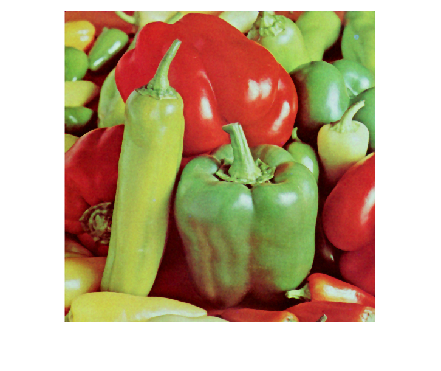

imshow(FilteredImage2c); 

[RMSE_Y, PSNR_Y, RMSE_RGB, PSNR_RGB] = RMSE_PSNR(Image,FilteredImage2c);
disp("RMSE Y channel")

RMSE Y channel


disp(RMSE_Y)

    6.7929



disp("PSNR Y channel")

PSNR Y channel


disp(PSNR_Y)

   31.4897



disp("RMSE RGB channel")

RMSE RGB channel


disp(RMSE_RGB)

    7.9960   11.0562    8.2042



disp("PSNR RGB channel")

PSNR RGB channel


disp(PSNR_RGB)

   30.0733   27.2587   29.8501



FilteredImage2d= median_filtering(NoiseImage1b,"RGB"); 
disp("Median Filter for Additive Gaussian Noise RGB Channel Image");

Median Filter for Additive Gaussian Noise RGB Channel Image


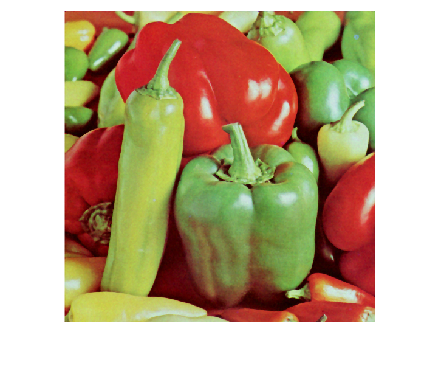

imshow(FilteredImage2d); 

[RMSE_Y, PSNR_Y, RMSE_RGB, PSNR_RGB] = RMSE_PSNR(Image,FilteredImage2d);
disp("RMSE Y channel")

RMSE Y channel


disp(RMSE_Y)

    6.7867



disp("PSNR Y channel")

PSNR Y channel


disp(PSNR_Y)

   31.4976



disp("RMSE RGB channel")

RMSE RGB channel


disp(RMSE_RGB)

    7.9771   11.0671    8.1903



disp("PSNR RGB channel")

PSNR RGB channel


disp(PSNR_RGB)

   30.0939   27.2501   29.8648





FilteredImage3 = DRID_filtering(NoiseImage2,3,10,"Luminosty");
disp("DRID Filter for Random Impulse Noise Y Channel Image");

DRID Filter for Random Impulse Noise Y Channel Image


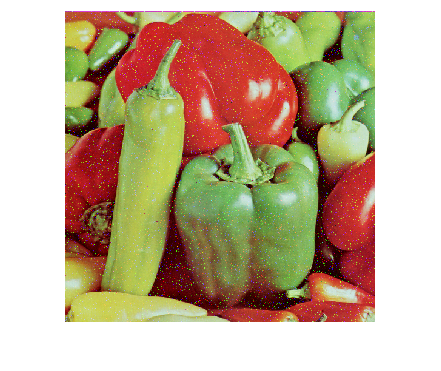

imshow(FilteredImage3); 

[RMSE_Y, PSNR_Y, RMSE_RGB, PSNR_RGB] = RMSE_PSNR(Image,FilteredImage3);
disp("RMSE Y channel")

RMSE Y channel


disp(RMSE_Y)

   10.1688



disp("PSNR Y channel")

PSNR Y channel


disp(PSNR_Y)

   27.9854



disp("RMSE RGB channel")

RMSE RGB channel


disp(RMSE_RGB)

   11.8936   18.4473   22.4598



disp("PSNR RGB channel")

PSNR RGB channel


disp(PSNR_RGB)

   26.6245   22.8122   21.1027



FilteredImage3b = DRID_filtering(NoiseImage2b,3,10,"RGB");
disp("DRID Filter for Random Impulse Noise RGB Channel Image");

DRID Filter for Random Impulse Noise RGB Channel Image


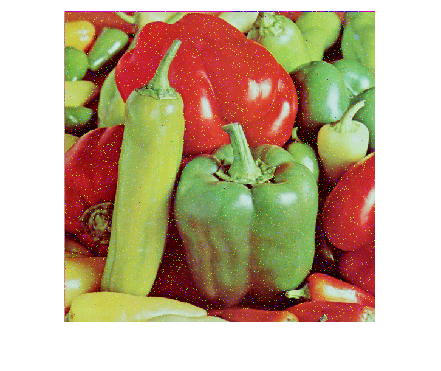

imshow(FilteredImage3b); 

[RMSE_Y, PSNR_Y, RMSE_RGB, PSNR_RGB] = RMSE_PSNR(Image,FilteredImage3b);
disp("RMSE Y channel")

RMSE Y channel


disp(RMSE_Y)

   10.1717



disp("PSNR Y channel")

PSNR Y channel


disp(PSNR_Y)

   27.9830



disp("RMSE RGB channel")

RMSE RGB channel


disp(RMSE_RGB)

   11.6486   18.5019   22.4591



disp("PSNR RGB channel")

PSNR RGB channel


disp(PSNR_RGB)

   26.8053   22.7865   21.1030



FilteredImage3c = DRID_filtering(NoiseImage1,3,10,"Luminosty");
disp("DRID Filter for Additive Gaussian Noise Y Channel Image");

DRID Filter for Additive Gaussian Noise Y Channel Image


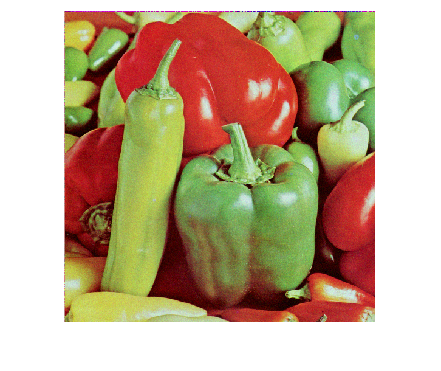

imshow(FilteredImage3c); 

[RMSE_Y, PSNR_Y, RMSE_RGB, PSNR_RGB] = RMSE_PSNR(Image,FilteredImage3c);
disp("RMSE Y channel")

RMSE Y channel


disp(RMSE_Y)

    4.8491



disp("PSNR Y channel")

PSNR Y channel


disp(PSNR_Y)

   34.4176



disp("RMSE RGB channel")

RMSE RGB channel


disp(RMSE_RGB)

    5.8341    8.7674    4.7565



disp("PSNR RGB channel")

PSNR RGB channel


disp(PSNR_RGB)

   32.8114   29.2733   34.5851



FilteredImage3d = DRID_filtering(NoiseImage1b,3,10,"RGB");
disp("DRID Filter for Additive Gaussian Noise RGB Channel Image");

DRID Filter for Additive Gaussian Noise RGB Channel Image


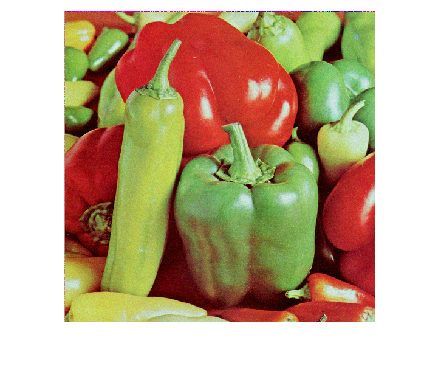

imshow(FilteredImage3d); 

[RMSE_Y, PSNR_Y, RMSE_RGB, PSNR_RGB] = RMSE_PSNR(Image,FilteredImage3d);
disp("RMSE Y channel")

RMSE Y channel


disp(RMSE_Y)

    4.9068



disp("PSNR Y channel")

PSNR Y channel


disp(PSNR_Y)

   34.3148



disp("RMSE RGB channel")

RMSE RGB channel


disp(RMSE_RGB)

    5.7861    8.8744    4.7460



disp("PSNR RGB channel")

PSNR RGB channel


disp(PSNR_RGB)

   32.8831   29.1681   34.6043



## Function Definitions

function [RMSE_Y, PSNR_Y, RMSE_RGB, PSNR_RGB] = RMSE_PSNR(image1,image2) % 

ImageDimensions1 = size(image1); % Finding the dimensions of the first image array,rows being N and columns as M
rows1 = ImageDimensions1(1,1);
columns1 = ImageDimensions1(1,2);

ImageDimensions2 = size(image2); % Finding the dimensions of the first image array,rows being N and columns as M
rows2 = ImageDimensions2(1,1);
columns2 = ImageDimensions2(1,2);

if((rows1~=rows2) || (columns1~=columns2))      % Keeping to see if the image dimensions match 
    disp("Can not find the RMSE and PSNR of these two images because their sizes are not the same.") % Display to the user the error 
    return;                                     % Return because the function can not be carried out 
end 

%-------- Y channel -------% 
YCBCR1 = rgb2ycbcr(image1);
[YImage1, cbImage1, crImage1] = imsplit(YCBCR1);
YImage1 = double(YImage1);

YCBCR2 = rgb2ycbcr(image2);
[YImage2, cbImage2, crImage2] = imsplit(YCBCR2);
YImage2 = double(YImage2);

sum_Y = 0;

%------ RGB channel -------- %

[R1, G1, B1] = imsplit(image1);
[R2, G2, B2] = imsplit(image2);

R1 = double(R1);
R2 = double(R2);
G1 = double(G1);
G2 = double(G2);
B1 = double(B1);
B2 = double(B2);

sum_R = 0;
sum_G = 0;
sum_B = 0;


for i = 1:rows1
    for j = 1:columns1
        % Luminosity channel
        diff_Y = YImage1(i, j) - YImage2(i, j);
        sum_Y = sum_Y + diff_Y^2;

        % Red channel
        diff_R = R1(i, j) - R2(i, j);
        sum_R = sum_R + diff_R^2;

        % Green channel
        diff_G = G1(i, j) - G2(i, j);
        sum_G = sum_G + diff_G^2;

        % Blue channel
        diff_B = B1(i, j) - B2(i, j);
        sum_B = sum_B + diff_B^2;
    end
end
% End outter loop 

MSE_Y = sum_Y / (rows1 * columns1);
RMSE_Y = sqrt(MSE_Y);

MSE_R = sum_R / (rows1 * columns1);
RMSE_R = sqrt(MSE_R);

MSE_G = sum_G / (rows1 * columns1);
RMSE_G = sqrt(MSE_G);

MSE_B = sum_B / (rows1 * columns1);
RMSE_B = sqrt(MSE_B);

% PSNR calculations
PSNR_Y = 20 * log10(255 / RMSE_Y);
PSNR_R = 20 * log10(255 / RMSE_R);
PSNR_G = 20 * log10(255 / RMSE_G);
PSNR_B = 20 * log10(255 / RMSE_B);

% Assign outputs
RMSE_RGB = [RMSE_R, RMSE_G, RMSE_B];
PSNR_RGB = [PSNR_R, PSNR_G, PSNR_B];

end
% ----------------------------------- END OF RMSE AND PSNR FUNCTION ----------------------------------- %

function [mean_Y,stand_Y,mean_RGB, stand_RGB] = mean_std(image)

% ------- Using DIFFERENT channel ------ %
YCBCR = rgb2ycbcr(image);
[YImage, cbImage, crImage] = imsplit(YCBCR);
YImage = double(YImage);

[R, G, B] = imsplit(image);

imageR = double(R);
imageG = double(G);
imageB = double(B);


ImageDimensions = size(YImage); % Finding the dimensions of the image array,rows being N and columns as M
rows = ImageDimensions(1,1);
columns = ImageDimensions(1,2);

meanSum_Y = 0 ;  % Setting a sum variable to calculate mean 
sum_Y = 0; % Setting a sum varibale which will be used to calculate variance 

meanSum_R = 0 ;  % Setting a sum variable to calculate mean 
sum_R = 0; % Setting a sum varibale which will be used to calculate variance 

meanSum_G = 0 ;  % Setting a sum variable to calculate mean 
sum_G = 0; % Setting a sum varibale which will be used to calculate variance 

meanSum_B = 0 ;  % Setting a sum variable to calculate mean 
sum_B = 0; % Setting a sum varibale which will be used to calculate variance 


% Looping through the image array to find mean values 
for i = 1:1:rows  
    for j = 1:1:columns
        meanSum_Y = meanSum_Y + YImage(i,j); % Updating sum variable 
        meanSum_R = meanSum_R + imageR(i,j); % Updating sum variable 
        meanSum_G = meanSum_G + imageG(i,j); % Updating sum variable 
        meanSum_B = meanSum_B + imageB(i,j); % Updating sum variable 
    end 
end 

mean_Y = meanSum_Y/(rows*columns);    % Finding the mean (sampling mean)
mean_R = meanSum_R/(rows*columns);    % Finding the mean (sampling mean)
mean_G = meanSum_G/(rows*columns);    % Finding the mean (sampling mean)
mean_B = meanSum_B/(rows*columns);    % Finding the mean (sampling mean)

% Looping through the image arry to find the Variance 
for i = 1:1:rows  
    for j = 1:1:columns
        x = YImage(i,j) - mean_Y;
        sum_Y = sum_Y + x^2; % Updating sum variable 

        x = imageR(i,j) - mean_R;
        sum_R = sum_R + x^2; % Updating sum variable 

        x = imageG(i,j) - mean_G;
        sum_G = sum_G + x^2; % Updating sum variable 

        x = imageB(i,j) - mean_B;
        sum_B = sum_B + x^2; % Updating sum variable 
    end 
end 

variance_Y = sum_Y/(rows*columns); % Finding the variance (sampling variance)
stand_Y = sqrt(variance_Y);   % Finding the standard deviation 

variance_R = sum_R/(rows*columns); % Finding the variance (sampling variance)
stand_R = sqrt(variance_R);   % Finding the standard deviation 

variance_G = sum_G/(rows*columns); % Finding the variance (sampling variance)
stand_G = sqrt(variance_G);   % Finding the standard deviation 

variance_B = sum_B/(rows*columns); % Finding the variance (sampling variance)
stand_B = sqrt(variance_B);   % Finding the standard deviation 


    mean_RGB = [mean_R, mean_G, mean_B];
    stand_RGB = [stand_R, stand_G, stand_B];


end 
% ----------------------------------- END OF MEAN AND STD FUNCTION ----------------------------------- %

        function [NoiseImage] = Gaussian_additive_noise(image, coefficient,channel)
               
                if(channel == "Luminosity")
                    YCBCR = rgb2ycbcr(image);
                    [YImage, cbImage, crImage] = imsplit(YCBCR);

                    image2 = double(YImage); % Converting unit8 type to double
                    
                    meanSum = 0 ;               % Setting a sum variable to calculate mean 
                    sum = 0;                    % Setting a sum varibale which will be used to calculate variance 
                    
                    [rows, columns] = size(YImage);

                    for i = 1:1:rows  
                        for j = 1:1:columns
                            meanSum = meanSum + image2(i,j);  % Updating sum variable 
                        end 
                    end 
                    
                    mean = meanSum/(rows*columns);           % Finding the mean (sampling mean)
                    
                                                             % Looping through the image arry to find the Variance 
                    for i = 1:1:rows  
                        for j = 1:1:columns
                            x = image2(i,j) - mean;
                            sum = sum + x^2;                 % Updating sum variable 
                        end 
                    end 
                    
                    variance = sum/(rows*columns);           % Finding the variance (sampling variance)
                    stand = sqrt(variance);                  % Finding the standard deviation 
                    
                    Noise = randn(rows, columns);
                    Noise = (stand * coefficient) * Noise + mean;
            
                    % Add noise to the luminance channel
                    NoiseImage = image2 + Noise - mean; % take mean away?

                    NoiseImage = uint8(NoiseImage);
                    NoiseImage = cat(3, NoiseImage, cbImage, crImage);
                    NoiseImage =  ycbcr2rgb(NoiseImage);

                else 
                    [R, G, B] = imsplit(image);

                    imageR = double(R);
                    imageG = double(G);
                    imageB = double(B);

                    meanSumR = 0 ;               % Setting a sum variable to calculate mean 
                    sumR = 0;                    % Setting a sum varibale which will be used to calculate variance 
                    meanSumG = 0 ;               % Setting a sum variable to calculate mean 
                    sumG = 0;                    % Setting a sum varibale which will be used to calculate variance 
                    meanSumB = 0 ;               % Setting a sum variable to calculate mean 
                    sumB = 0;                    % Setting a sum varibale which will be used to calculate variance 

                    ImageDimensions = size(image); % Finding the dimensions of the image array,rows being N and columns as M
                    rows = ImageDimensions(1,1);
                    columns = ImageDimensions(1,2);

                    for i = 1:1:rows  
                        for j = 1:1:columns
                            meanSumR = meanSumR + imageR(i,j);  % Updating sum variable 
                            meanSumG = meanSumG + imageG(i,j);  % Updating sum variable
                            meanSumB = meanSumB + imageB(i,j);  % Updating sum variable
                        end 
                    end 

                    meanR = meanSumR/(rows*columns);           % Finding the mean (sampling mean)
                    meanG = meanSumG/(rows*columns);           % Finding the mean (sampling mean)
                    meanB = meanSumB/(rows*columns);           % Finding the mean (sampling mean)

                    for i = 1:1:rows  
                        for j = 1:1:columns
                            xR = imageR(i,j) - meanR;
                            xG = imageG(i,j) - meanG;
                            xB = imageB(i,j) - meanB;
                            sumR = sumR + xR^2;                 % Updating sum variable 
                            sumG = sumG + xG^2;                 % Updating sum variable 
                            sumB = sumB + xB^2;                 % Updating sum variable 
                        end 
                    end 

                    varianceR = sumR/(rows*columns);           % Finding the variance (sampling variance)
                    standR = sqrt(varianceR);                  % Finding the standard deviation 

                    varianceG = sumG/(rows*columns);           % Finding the variance (sampling variance)
                    standG = sqrt(varianceG);                  % Finding the standard deviation 
                    
                    varianceB = sumB/(rows*columns);           % Finding the variance (sampling variance)
                    standB = sqrt(varianceB);                  % Finding the standard deviation 
                    
                        % Generate Gaussian noise for each channel
                        NoiseR = (standR * coefficient) * randn(rows, columns) + meanR;
                        NoiseG = (standG * coefficient) * randn(rows, columns) + meanG;
                        NoiseB = (standB * coefficient) * randn(rows, columns) + meanB;
                
                        % Add noise to each channel
                        NoiseImageR = imageR + NoiseR - meanR; %remove means?
                        NoiseImageG = imageG + NoiseG - meanG;
                        NoiseImageB = imageB + NoiseB - meanB;
                
                        % combine channels
                        NoiseImageR = uint8(min(max(NoiseImageR, 0), 255));
                        NoiseImageG = uint8(min(max(NoiseImageG, 0), 255));
                        NoiseImageB = uint8(min(max(NoiseImageB, 0), 255));
                
                        NoiseImage = cat(3, NoiseImageR, NoiseImageG, NoiseImageB);
                    
                end                                      
             end

% ----------- END OF GAUSSIAN NOISE FUNCTION -----------------%%%

        function [NoiseImage] = impulse_noise(image,corruption_rate, channel) 
               
                if(channel == "Luminosity")

                    YCBCR = rgb2ycbcr(image);
                    [YImage, cbImage, crImage] = imsplit(YCBCR);
                    image2 = double(YImage);
                        
                        ImageDimensions = size(image); % Finding the dimensions of the image array,rows being N and columns as M
                        rows = ImageDimensions(1,1);
                        columns = ImageDimensions(1,2);
                        
                        NoiseImage = image2;                % Creating the new noise image 
                        
                            %p = corruption_rate/100;        % Calculation propbablity rate if corruption rate is given in percentage  
                            p_n = (rows*columns)*corruption_rate;         % Calc number of corruputed pixels 
                        
                    n_min = 0;  % The range was given to us so we know min is 0 
                    n_max = 255; % The range was given to us so we know max is 255 
                    
                            for i=1:p_n                     % Looping through p_n range 
                                x = randi(rows);            % Generate random x
                                y = randi(columns);         % Generate random y
                                NoiseImage(x,y) = randi([n_min,n_max]);      % Change intesity value
                            end   
                    
                            NoiseImage = uint8(NoiseImage);
                    NoiseImage = cat(3, NoiseImage, cbImage, crImage);
                    NoiseImage =  ycbcr2rgb(NoiseImage);

                else 

                    [R, G, B] = imsplit(image);

                    NoiseImage = image;
                    noiseR = double(R); 
                    noiseG = double(G); 
                    noiseB = double(B);

                    ImageDimensions = size(image); % Finding the dimensions of the image array,rows being N and columns as M
                    rows = ImageDimensions(1,1);
                    columns = ImageDimensions(1,2);
                
                    p_n = (rows*columns)*corruption_rate;         % Calc number of corruputed pixels 
                
                    n_min = 0;  % The range was given to us so we know min is 0 
                    n_max = 255; % The range was given to us so we know max is 255 
                    
                    for i=1:p_n                     % Looping through p_n range 
                        x_r = randi(rows);            % Generate random x
                        y_r = randi(columns);         % Generate random y
                        x_g = randi(rows);            % Generate random x
                        y_g = randi(columns);         % Generate random y
                        x_b = randi(rows);            % Generate random x
                        y_b = randi(columns);         % Generate random y
                        noiseR(x_r,y_r) = randi([n_min,n_max]); % Change intesity value
                        noiseG(x_g,y_g) = randi([n_min,n_max]); % Change intesity value
                        noiseB(x_b,y_b) = randi([n_min,n_max]);% Change intesity value
                    end 
                        % combine channels
                        noiseR = uint8(noiseR);
                        noiseG = uint8(noiseG);
                        noiseB = uint8(noiseB);
               
                        NoiseImage = cat(3, noiseR, noiseG, noiseB);
                end
                    NoiseImage = uint8(NoiseImage);                                     % Converting the image to uint8 type 
             end
% ----------- END OF IMPULSE NOISE FUNCTION -----------------%%%

% ---------------------------- MIRROR FUNCTION ------------------------------%%%

function [ C ] = mirrorImage( image,kernel )
% This function extends an image contained in the image matrix
% mirroring it in all directions to be able then to use a local window
% of the kernel x kernel size (kernel = 3, 5, or 7) around each pixel

C = image;
imSize = size(C);
rowSize = imSize(1);
colSize = imSize(2);

%get the right size mirror depending on the size of the window
if kernel == 3
    mirror = 3;
end
if kernel == 5
    mirror = 4;
     
end
if kernel == 7
    mirror = 5;
   
end

%this section mirrors the top and left
diff = 1;% used to help grab the right row for mirroring of different size windows
for l = 3: mirror
C = [ C(1:rowSize,l-diff) C];
colSize = colSize + 1;
C = [ C(l-diff,1:colSize); C];
rowSize = rowSize + 1;

diff = diff - 1;
end

%this section mirrors the bottom and right
diff = 0;% used to grab the correct row because it changes with each
            %increase in column and row
 for t = 1 : mirror - 2
C = [C C(1:rowSize, colSize - t - diff)];
colSize = colSize + 1;
diff = diff + 1;
 end
 diff = 0;
 for s = 1 : mirror - 2
C = [C ; C(rowSize - s - diff, 1:colSize)];
rowSize = rowSize + 1;
diff = diff + 1;
 end

end
% ----------- END OF MIRROR  FUNCTION -----------------%%%


% -------------------------------- Median Filter ----------------------------------- %

function [FilteredImage] = median_filtering(image,channel) 
            
                ImageDimensions = size(image); % Finding the dimensions of the image array,rows being N and columns as M
                rows = ImageDimensions(1,1);
                columns = ImageDimensions(1,2);
                FilteredImage = zeros(rows,columns);

                if channel == "Luminosity"
                    % ------ Using Y Channel ------ %
                    YCBCR = rgb2ycbcr(image);
                    [YImage, cbImage, crImage] = imsplit(YCBCR);
                                        
                    
                    mirror_imageY = mirrorImage(YImage,3);
                    mirror_imageY = double(mirror_imageY); % Converting unit8 type to double
                    
                    
                    for x = 2:rows+1
                        for y = 2:columns+1
                            window = mirror_imageY(x-1:x+1, y-1:y+1);        % 3x3 window 
                            window = window(:);                             % Vecotrize the matrix 
                            window = sorting(window, 9);                    % Sort the array
                            FilteredImage(x-1,y-1) = window(5);             % Replace intensity with median of the 1x9 array 
                        end
                    end
                    
                    FilteredImage = cat(3, FilteredImage, cbImage, crImage);
                    FilteredImage =  ycbcr2rgb(FilteredImage);
                    FilteredImage = uint8(FilteredImage);
                else  
                    % ------ Using RGB Channels ------ %
                    [R, G, B] = imsplit(image);
                                            
                    mirror_imageR = mirrorImage(R,3);
                    mirror_imageR = double(mirror_imageR); 
                    
                    mirror_imageG = mirrorImage(G,3);
                    mirror_imageG = double(mirror_imageG); 
                    
                    mirror_imageB = mirrorImage(B,3);
                    mirror_imageB = double(mirror_imageB); 
                    
                    FilteredImageR = zeros(rows,columns);
                    FilteredImageG = zeros(rows,columns);
                    FilteredImageB = zeros(rows,columns);
                    
                    for x = 2:rows+1
                        for y = 2:columns+1
                            
                            windowR = mirror_imageR(x-1:x+1, y-1:y+1);        % 3x3 window 
                            windowR = windowR(:);                             % Vecotrize the matrix 
                            windowR = sorting(windowR, 9);                    % Sort the array
                            FilteredImageR(x-1,y-1) = windowR(5);             % Replace intensity with median of the 1x9 array 
                            
                            windowG = mirror_imageG(x-1:x+1, y-1:y+1);        % 3x3 window 
                            windowG = windowG(:);                             % Vecotrize the matrix 
                            windowG = sorting(windowG, 9);                    % Sort the array
                            FilteredImageG(x-1,y-1) = windowG(5);             % Replace intensity with median of the 1x9 array 
                    
                            windowB = mirror_imageB(x-1:x+1, y-1:y+1);        % 3x3 window 
                            windowB = windowB(:);                             % Vecotrize the matrix 
                            windowB = sorting(windowB, 9);                    % Sort the array
                            FilteredImageB(x-1,y-1) = windowB(5);             % Replace intensity with median of the 1x9 array 
                        end
                    end
                    
                    FilteredImage = cat(3, FilteredImageR, FilteredImageG, FilteredImageB);
                    FilteredImage = uint8(FilteredImage);
                end 
            end 
            
            function [sorted_array] = sorting(A, size)
            
            for j = 2:size
                key = A(j);
                i=j-1;
                while(i>0 && key<A(i))
                    A(i+1)=A(i);
                    i=i-1;
                end 
                A(i+1)=key;
            end
            sorted_array = A;
end 

% ---------------------------- END OF MEDIAN FILTERING FUNCTION ------------------------------%%%

 % -------------------------- RANK ORDER MEAN EV FUNCTION ------------------------------------%%%
function [FilteredImage] = rank_order_Mean_EV_filtering(image,channel)
                
                ImageDimensions = size(image); % Finding the dimensions of the image array,rows being N and columns as M
                rows = ImageDimensions(1,1);
                columns = ImageDimensions(1,2);
                FilteredImage = zeros(rows,columns);

                    if(channel == "Luminosity")
                        % ------- Using Y channel ------ %
                        YCBCR = rgb2ycbcr(image);
                        [YImage, cbImage, crImage] = imsplit(YCBCR);
                                                              % Looping through the image array to find the max, min, and mean values 
                        mirror_image = mirrorImage(YImage,3);
                        mirror_image = double(mirror_image); % Converting unit8 type to double
                        
                        E_v = std(double(YImage)); 
                        
                        for x = 2:rows+1
                            for y = 2:columns+1
                                window = mirror_image(x-1:x+1, y-1:y+1);        % 3x3 window of noise 
                                window = window(:);                             % Vecotrize the matrix into an 1D array 
                                window = sort(window);                    % Sort the array to get variational series 
                        
                                EV_set= []; % Get EV set 
                                for i =1:9                                      % Looping through variational series 
                                    if((mirror_image(x,y) - window(i)) <= E_v)  % Checking condition if those intensity values whose difference from the intensity value in the pixel of interest does not exceed E_V
                                        EV_set(end+1,1) = window(i);            % Adding that insentisty value to the end of the EV set 
                                    end                                         % End if staement 
                                end                                             % End for loop 
                                
                                l = length(EV_set);   % Get size of set 
                                sum_=0;
                                for i= 1:l
                                    sum_=sum_+EV_set(i);  % Update sum to get mean
                                end
                        
                                Mean_EV = sum_/l;                       % Finding the mean of the EV set 
                                FilteredImage(x-1,y-1) = Mean_EV;             % Replace intensity with EV mean 
                            end
                        end
                        
                        FilteredImage = cat(3, FilteredImage, cbImage, crImage);
                        FilteredImage =  ycbcr2rgb(FilteredImage);
                        FilteredImage = uint8(FilteredImage);
                        
                    else 
                        % ------- Using RGB channels ------ %
                        [R, G, B] = imsplit(image);
                        
                        imageR = double(R);
                        imageG = double(G);
                        imageB = double(B);
                        
                        mirror_imageR = mirrorImage(imageR,3);
                        mirror_imageR = double(mirror_imageR); 
                        
                        mirror_imageG = mirrorImage(imageG,3);
                        mirror_imageG = double(mirror_imageG); 
                        
                        mirror_imageB = mirrorImage(imageB,3);
                        mirror_imageB = double(mirror_imageB); 
                        
                        FilteredImageR = zeros(rows,columns);
                        FilteredImageG = zeros(rows,columns);
                        FilteredImageB = zeros(rows,columns);
                        
                        
                        E_v_R = std(double(imageR)); 
                       
                        E_v_G = std(double(imageG)); 
                        
                        E_v_B = std(double(imageB));
                                                               
                        for x = 2:rows+1
                            for y = 2:columns+1
                                windowR = mirror_imageR(x-1:x+1, y-1:y+1);       % 3x3 window of noise
                                windowR = windowR(:);                             % Vecotrize the matrix 
                                windowR = sort(windowR);                    % Sort the array to get variational series 
                                
                                windowG = mirror_imageG(x-1:x+1, y-1:y+1);        % 3x3 window of noise
                                windowG = windowG(:);                             % Vecotrize the matrix 
                                windowG = sort(windowG);                    % Sort the array to get variational series 
                        
                                windowB = mirror_imageB(x-1:x+1, y-1:y+1);        % 3x3 window of noise
                                windowB = windowB(:);                             % Vecotrize the matrix 
                                windowB = sort(windowB);                    % Sort the array to get variational series 
                        
                        
                                EV_set_R= []; % Get EV_R set 
                                EV_set_G= []; % Get EV_G set 
                                EV_set_B= []; % Get EV_B set 
                        
                                for i =1:9                                      % Looping through variational series 
                                    if((mirror_imageR(x,y) - windowR(i)) <= E_v_R)  % Checking condition if those intensity values whose difference from the intensity value in the pixel of interest does not exceed E_V
                                        EV_set_R(end+1,1) = windowR(i);            % Adding that insentisty value to the end of the EV set 
                                    end                                         % End if staement 
                        
                                    if((mirror_imageG(x,y) - windowG(i)) <= E_v_G)  % Checking condition if those intensity values whose difference from the intensity value in the pixel of interest does not exceed E_V
                                        EV_set_G(end+1,1) = windowG(i);            % Adding that insentisty value to the end of the EV set 
                                    end                                         % End if staement 
                        
                                    if((mirror_imageB(x,y) - windowB(i)) <= E_v_B)  % Checking condition if those intensity values whose difference from the intensity value in the pixel of interest does not exceed E_V
                                        EV_set_B(end+1,1) = windowB(i);            % Adding that insentisty value to the end of the EV set 
                                    end                                         % End if staement 
                                end                                             % End for loop 
                                
                                l = length(EV_set_R);   % Get size of set 
                                sum_=0;
                                for i= 1:l
                                    sum_=sum_+EV_set_R(i);  % Update sum to get mean
                                end
                                Mean_EV = sum_/l;                       % Finding the mean of the EV set 
                                FilteredImageR(x-1,y-1) = Mean_EV;             % Replace intensity with EV mean 
                        
                        
                                l = length(EV_set_G);   % Get size of set 
                                sum_=0;
                                for i= 1:l
                                    sum_=sum_+EV_set_G(i);  % Update sum to get mean
                                end
                                Mean_EV = sum_/l;                       % Finding the mean of the EV set 
                                FilteredImageG(x-1,y-1) = Mean_EV;             % Replace intensity with EV mean 
                        
                        
                                l = length(EV_set_B);   % Get size of set 
                                sum_=0;
                                for i= 1:l
                                    sum_=sum_+EV_set_B(i);  % Update sum to get mean
                                end
                                Mean_EV = sum_/l;                       % Finding the mean of the EV set 
                                FilteredImageB(x-1,y-1) = Mean_EV;             % Replace intensity with EV mean       
                            end
                        end
                        
                        FilteredImage = cat(3, FilteredImageR, FilteredImageG, FilteredImageB);
                        FilteredImage = uint8(FilteredImage);
                    end
end 
% ----------- END OF RANK ORDER MEAN EV FUNCTION -----------------%%%


 % --------------- differential rank impulse detector (DRID) -------------- %%
function [FilteredImage] = DRID_filtering(image,r,s, channel) 
                       
                        ImageDimensions = size(image); % Finding the dimensions of the image array,rows being N and columns as M
                        rows = ImageDimensions(1,1);
                        columns = ImageDimensions(1,2);
                        FilteredImage = zeros(rows,columns);    

                if(channel == "Luminosity")
                        % ------- Using Y channel ------ %
                        YCBCR = rgb2ycbcr(image);
                        [YImage, cbImage, crImage] = imsplit(YCBCR);
                                                           
                        mirror_image = mirrorImage(YImage,3);
                        mirror_image = double(mirror_image); % Converting unit8 type to double
                        
                        
                        for x = 2:rows+1
                            for y = 2:columns+1
                                window = mirror_image(x-1:x+1, y-1:y+1);        % 3x3 window of noise 
                                window = window(:);                             % Vecotrize the matrix into an 1D array 
                                window = sort(window);                    % Sort the array to get variational series 
                                
                                median_Y = median(window);
                                pixel_interest = mirror_image(x,y); 
                                index = find(window==pixel_interest);
                                
                                if index <=r
                                    difference = window(index+1) - window(index);
                                    if difference > s
                                        FilteredImage(x-1,y-1) = median_Y;             % Replace intensity it is an impulse
                                    else
                                        FilteredImage(x-1, y-1) = pixel_interest;
                                    end
                                elseif ((9-r)<index)
                                    difference = window(index-1)-window(index);
                                    if difference>s
                                         FilteredImage(x-1,y-1) = median_Y;             % Replace intensity it is an impulse
                                    else
                                        FilteredImage(x-1, y-1) = pixel_interest;
                                    end
                                else
                                    FilteredImage(x-1, y-1) = pixel_interest;
                                end
        
                            end
                        end
                        
                        FilteredImage = cat(3, FilteredImage, cbImage, crImage);
                        FilteredImage =  ycbcr2rgb(FilteredImage);
                        FilteredImage = uint8(FilteredImage);
                
                else 
                        % ------- Using RGB channels ------ %
                        [R, G, B] = imsplit(image);
                        
                        
                        mirror_imageR = mirrorImage(R,3);
                        mirror_imageR = double(mirror_imageR); 
                        
                        mirror_imageG = mirrorImage(G,3);
                        mirror_imageG = double(mirror_imageG); 
                        
                        mirror_imageB = mirrorImage(B,3);
                        mirror_imageB = double(mirror_imageB); 
                        
                        FilteredImageR = zeros(rows,columns);
                        FilteredImageG = zeros(rows,columns);
                        FilteredImageB = zeros(rows,columns);
                        
                                                               
                        for x = 2:rows+1
                            for y = 2:columns+1
                                windowR = mirror_imageR(x-1:x+1, y-1:y+1);       % 3x3 window of noise
                                windowR = windowR(:);                             % Vecotrize the matrix 
                                windowR = sort(windowR);                    % Sort the array to get variational series 
                                
                                windowG = mirror_imageG(x-1:x+1, y-1:y+1);        % 3x3 window of noise
                                windowG = windowG(:);                             % Vecotrize the matrix 
                                windowG = sort(windowG);                    % Sort the array to get variational series 
                        
                                windowB = mirror_imageB(x-1:x+1, y-1:y+1);        % 3x3 window of noise
                                windowB = windowB(:);                             % Vecotrize the matrix 
                                windowB = sort(windowB);                    % Sort the array to get variational series 
                        
                                medianR = median(windowR);
                                pixel_interestR = mirror_imageR(x,y); 
                                indexR = find(windowR==pixel_interestR);
        
                                medianG = median(windowG);
                                pixel_interestG = mirror_imageG(x,y); 
                                indexG = find(windowG==pixel_interestG);
        
                                medianB = median(windowB);
                                pixel_interestB = mirror_imageB(x,y); 
                                indexB = find(windowB==pixel_interestB);
        
                                if indexR <=r
                                    differenceR = windowR(indexR+1) - windowR(indexR);
                                    if differenceR > s
                                        FilteredImageR(x-1,y-1) = medianR;             % Replace intensity it is an impulse
                                    else
                                        FilteredImageR(x-1, y-1) = pixel_interestR;
                                    end
                                elseif ((9-r)<indexR)
                                    differenceR = windowR(indexR-1)-windowR(indexR);
                                    if differenceR>s
                                         FilteredImageR(x-1,y-1) = medianR;             % Replace intensity it is an impulse
                                    else
                                        FilteredImageR(x-1, y-1) = pixel_interestR;
                                    end
                                else
                                    FilteredImageR(x-1, y-1) = pixel_interestR;
                                end
        
        
                                 if indexG <=r
                                    differenceG = windowG(indexG+1) - windowG(indexG);
                                    if differenceG > s
                                        FilteredImageG(x-1,y-1) = medianG;             % Replace intensity it is an impulse
                                    else
                                        FilteredImageG(x-1, y-1) = pixel_interestG;
                                    end
                                elseif ((9-r)<indexG)
                                    differenceG = windowG(indexG-1)-windowG(indexG);
                                    if differenceG>s
                                         FilteredImageG(x-1,y-1) = medianG;             % Replace intensity it is an impulse
                                    else
                                        FilteredImageG(x-1, y-1) = pixel_interestG;
                                    end
                                else
                                    FilteredImageG(x-1, y-1) = pixel_interestG;
                                end
        
        
                                if indexB <=r
                                    differenceB = windowB(indexB+1) - windowB(indexB);
                                    if differenceB > s
                                        FilteredImageB(x-1,y-1) = medianB;             % Replace intensity it is an impulse
                                    else
                                        FilteredImageB(x-1, y-1) = pixel_interestB;
                                    end
                                elseif ((9-r)<indexB)
                                    differenceB = windowB(indexB-1)-windowB(indexB);
                                    if differenceB>s
                                         FilteredImageB(x-1,y-1) = medianB;             % Replace intensity it is an impulse
                                    else
                                        FilteredImageB(x-1, y-1) = pixel_interestB;
                                    end
                                else
                                    FilteredImageB(x-1, y-1) = pixel_interestB;
                                end
        
                            end
                        end
                        
                        FilteredImage = cat(3, FilteredImageR, FilteredImageG, FilteredImageB);
                        FilteredImage = uint8(FilteredImage);
                end
end 
                
                
 % -------------------------- END OF DRID FUNCTION ------------------------------------%%%
